# Step 9: 最適潮流計算

`calculate_optimal_powerflow` は、発電の費用が最小になる運転点を、電圧・出力・ブランチの制約のもとで求めます。結果は `ResultOPF` で返り、表・図・制約・地点別限界価格（LMP）で読めます。Optimization Toolbox を使います。

この Step は、GUILDA の基本的な流れの赤枠の部分です。

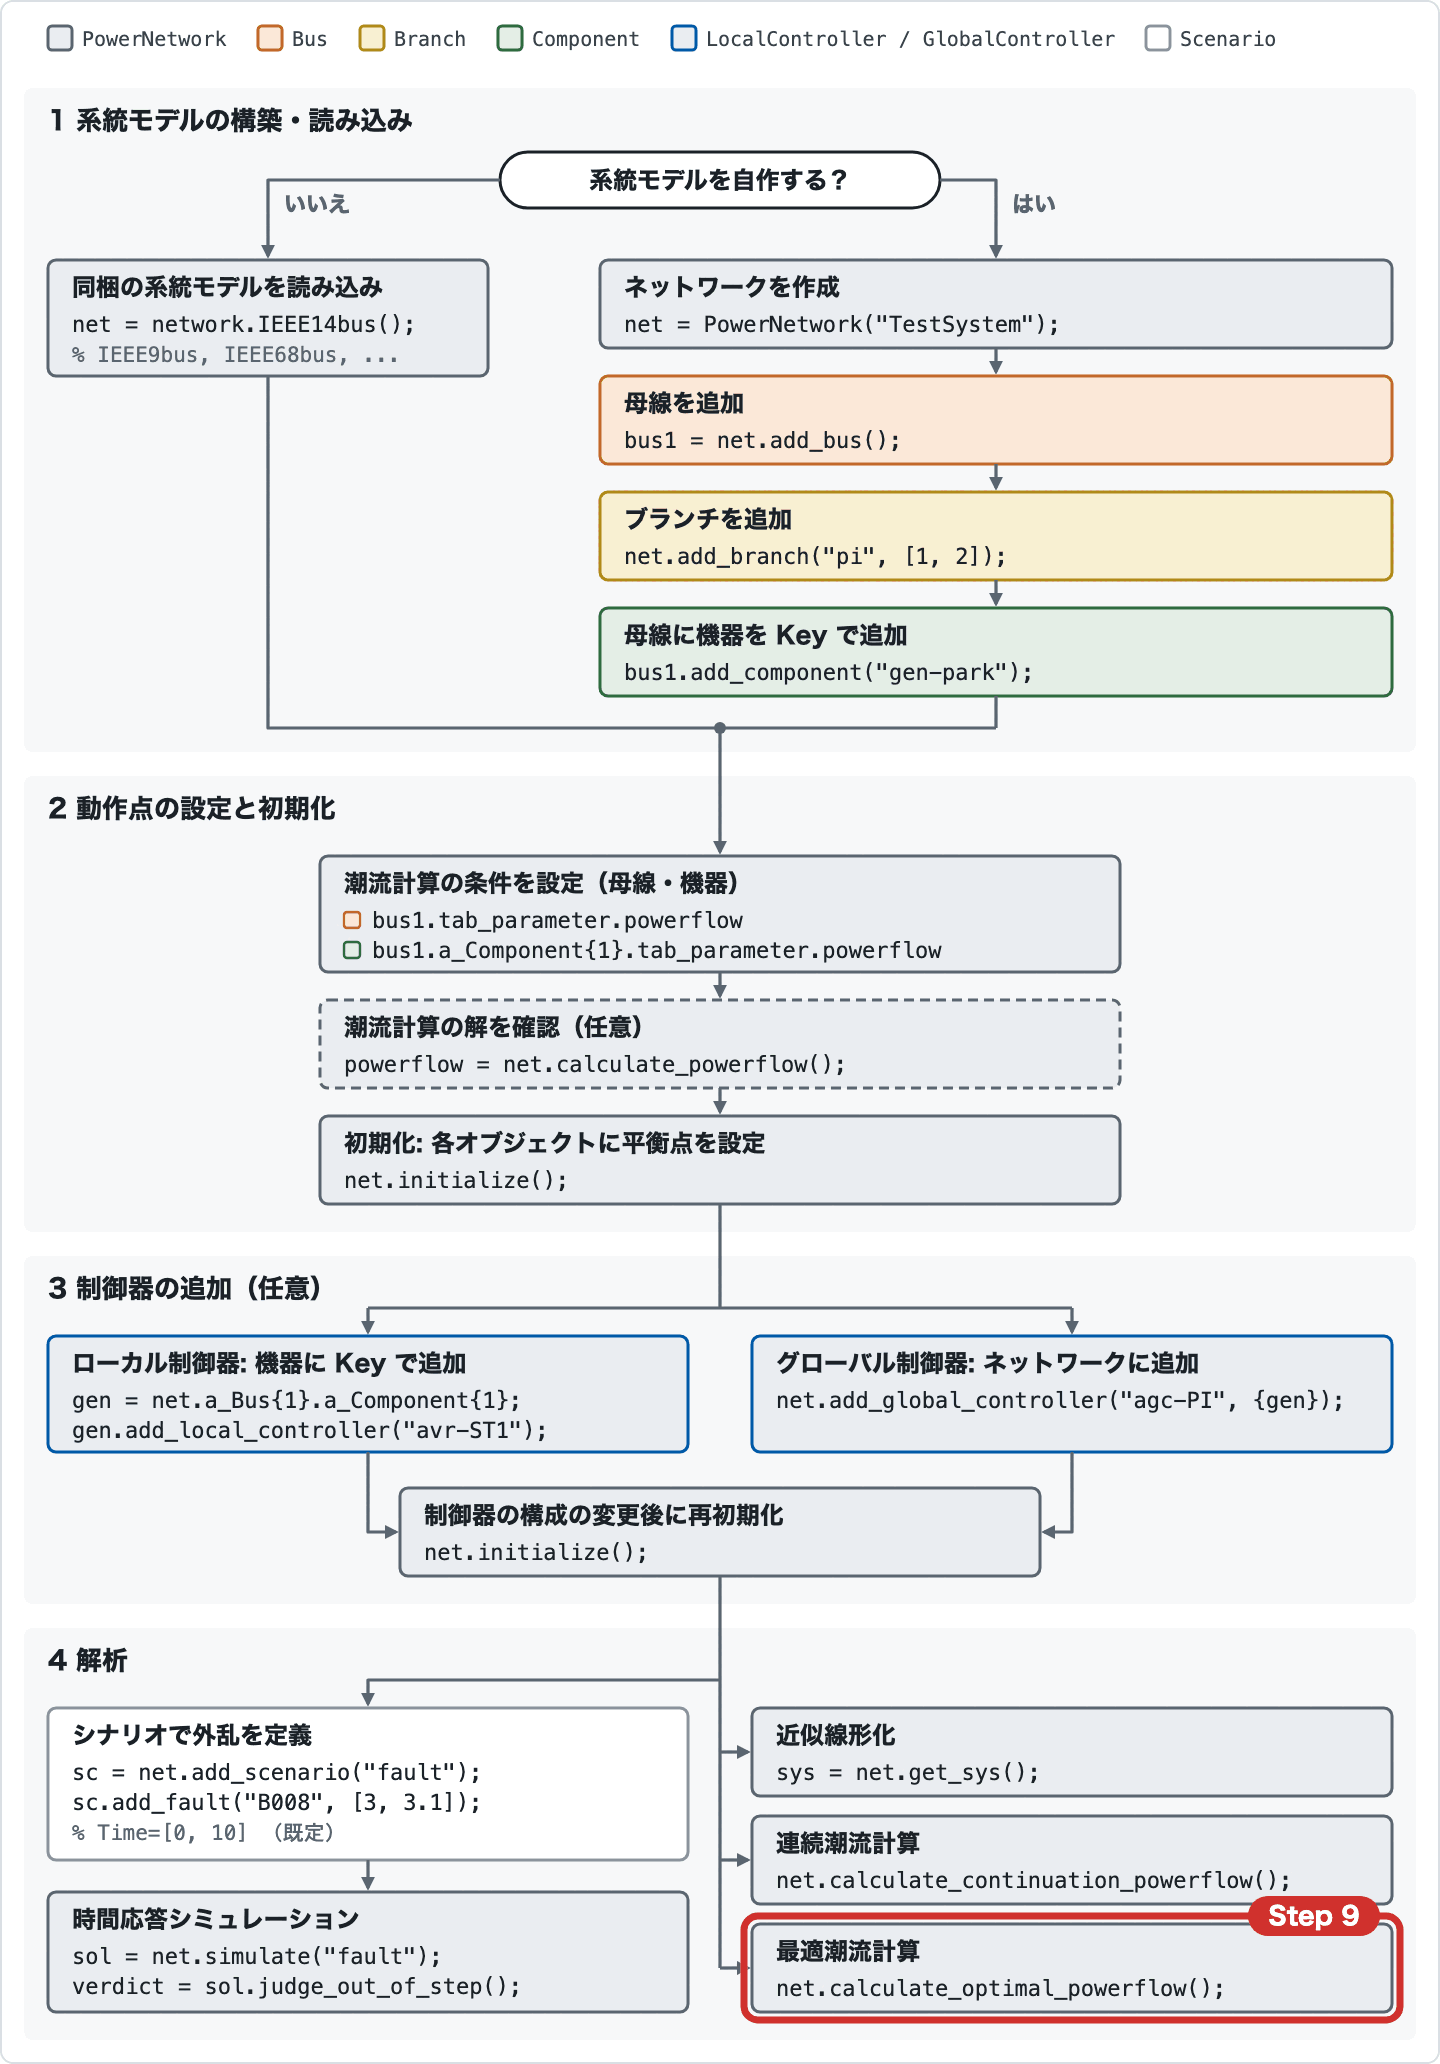

## この Step で分かること

- OPF の費用と制約の設定と、`get_opf_condition` での確認

- `calculate_optimal_powerflow` の 3 つの方法（`"ELD"`・`"DC OPF"`・`"AC OPF"`）

- `ResultOPF` の表と表示（`disp_summary`・`disp_binding`・`get_lmp`）

- 結果の図（`plot_dispatch`・`plot_lmp`・`plot_iteration`）

- 自分の費用と制約（`Cost`・`Constraint`）、問題を直接書き換える方法（`build_opf_problem`・`Problem`）

- 安定度制約付き OPF（`MinDampingRatio`・`MaxRealPart`）

各節は、最適潮流計算を解いて結果を出すのに要るコードだけで進みます。**確かめる（省略できます）** の下のコードは、中身を見るためのものです。飛ばしても最後まで動きます。

## 1. 費用と制約を設定して確かめる

同梱の IEEE 9 母線系統を読み込みます。

net = network.IEEE9bus(LocalController=true);

OPF の条件は、母線・機器・ブランチの `tab_parameter` にあります。

既定では 3 台の発電機の費用が同じなので、発電機ごとに費用の係数を変えます。母線電圧の上下限も、既定の 0.5〜1.5 pu から 0.95〜1.05 pu に狭めます。

多くの要素のパラメータは、`net.get_parameter(グループ, Class=...)` で表として取り出し、書き換えて `net.set_parameter(グループ, 表)` で書き戻します（Step 3）。行の名前はタグです。発電機の費用（`OPF`）と出力の上下限（`operation`）です。

tab_cost = net.get_parameter("OPF", Class="component.generator.abstract");
tab_cost.HP = [1100; 850; 1225];     % B001SG1, B002SG1, B003SG1
tab_cost.fP = [ 500; 120;  100];
net.set_parameter("OPF", tab_cost);
tab_gen = net.get_parameter("operation", Class="component.generator.abstract");
tab_gen.Pmin(:) = 0.1;
tab_gen.Pmax(:) = 2.0;
net.set_parameter("operation", tab_gen);

母線の電圧の上下限です。

tab_bus = net.get_parameter("operation", Class="Bus");
tab_bus.Vmin(:) = 0.95;
tab_bus.Vmax(:) = 1.05;
net.set_parameter("operation", tab_bus);

**確かめる（省略できます）**

`get_opf_condition` は、OPF が使う条件を母線・機器・ブランチの 3 つの表で表示します。

net.get_opf_condition();

Bus
            Vmin    Vmax    Gshunt    Bshunt     Type        V      Varg
            ____    ____    ______    ______    _______    _____    ____

    B001    0.95    1.05      0         0       "slack"     1.04     0  
    B002    0.95    1.05      0         0       "PV"       1.025     0  
    B003    0.95    1.05      0         0       "PV"       1.025     0  
    B004    0.95    1.05      0         0       "PQ"           1     0  
    B005    0.95    1.05      0         0       "PQ"           1     0  
    B006    0.95    1.05      0         0       "PQ"           1     0  
    B007    0.95    1.05      0         0       "PQ"           1     0  
    B008    0.95    1.05      0         0       "PQ"           1     0  
    B009    0.95    1.05      0         0       "PQ"           1     0  

Component
                 Bus       HP     fP     HQ    fQ    c     P0       Q0      Pmin     Pmax     Qmin     Qmax 
                ______    ____    ___    __    __    _    _____    _____

表を受け取るには `Display=false` にします。行の名前はタグです。

sct_cond = net.get_opf_condition(Display=false);
sct_cond.Component(["B001SG1", "B002SG1", "B003SG1"], ["HP", "fP", "Pmin", "Pmax"])

ans = 3×4 table
                HP     fP     Pmin    Pmax
               ____    ___    ____    ____

    B001SG1    1100    500    0.1      2  
    B002SG1     850    120    0.1      2  
    B003SG1    1225    100    0.1      2  


**注意:** 負荷は `Pmin = Pmax`（`Qmin = Qmax`）なので、潮流の値に固定されます。上下限を `Inf`（下限は `-Inf`）にすると、その制約はかかりません。母線ごと・ブランチごとの表は `net.get_element("B005").get_opf_condition()`、`net.get_element("EL008").get_opf_condition()` のように、要素の `get_opf_condition` でも見られます。

## 2. 最適潮流計算を実行する

`Method` で定式化を選びます。

[resELD, flagELD] = net.calculate_optimal_powerflow(Method="ELD");
resDC = net.calculate_optimal_powerflow(Method="DC OPF");
[resAC, flagAC] = net.calculate_optimal_powerflow(Method="AC OPF");

省いたオプションの値は `GUILDA.setting` の OptimalPowerFlow の項目から読みます。ソルバーの選び方、許容誤差、進み具合の表示、前回の解から始める指定などは、`calculate_optimal_powerflow` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=calculate_optimal_powerflow')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

**確かめる（省略できます）**

解けたかどうか（`flag`）と、3 つの方法の費用を比べます。AC OPF は送電線の損失もまかなうので、少し高くなります。

[flagELD, flagAC]

ans =     OptimalSolution    OptimalSolution


[resELD.r_cost, resDC.r_cost, resAC.r_cost]

ans = 1.0e+03 *

    4.1310    4.1310    4.2206


`get_summary` は、`disp_summary`（3 節）で表示する値を構造体で返します。発電・負荷・損失の合計を比べます。

sct_AC = resAC.get_summary();
[sct_AC.r_Pgeneration, sct_AC.r_Pload, sct_AC.r_Ploss]

ans =     3.1867    3.1500    0.0367


**注意:** 系統そのものは書き換えません。解を潮流の条件として使うには、結果の値を `tab_parameter.powerflow` に書いてから `net.initialize()` します。

## 3. 結果を読む

### ResultOPF のプロパティ

結果のオブジェクトと、母線ごとの表、発電機の注入の表を表示します。

resAC

resAC =   ResultOPF のプロパティ:

          tab_bus: [9×6 table]
          tab_cub: [24×3 table]
       tab_branch: [9×8 table]
           r_cost: 4.2206e+03
           lambda: [1×1 struct]
          OPFprob: [1×1 optim.problemdef.OptimizationProblem]
    sct_iteration: [1×1 struct]
    sct_stability: [1×1 struct]
      sct_network: [1×1 struct]
             flag: [1×1 optim.problemdef.Exitflag]
           output: [1×1 struct]
          options: [1×1 struct]
         s_solver: "SolverOPF"
        r_elapsed: 3.9530
        s_network: "PowerNetwork"
        l_success: 1


resAC.tab_bus

ans = 9×6 table
              Varg         V          P          Q            Vphasor              Iphasor      
            _________    ______    _______    ________    ________________    __________________

    B001            0      1.05    0.90139     0.18016      1.05+0i            0.85847-0.17158i 
    B002     0.092911      1.05     1.3432     0.06578    1.0455+0.097417i      1.2795+0.056304i
    B003     0.061247      1.04     0.9421    -0.15376     1.038+0.063656i     0.89512+0.20302i 
    B004    -0.047505    1.0413          0           0    1.0401-0.049448i           0+0i       
    B005    -0.089167    1.0165      -1.25        -0.5    1.0124-0.090516i     -1.1811+0.59945i 
    B006    -0.076754    1.0301       -0.9        -0.3     1.027-0.078985i    -0.84882+0.35738i 
    B007     0.016632    1.0491          0           0     1.049+0.017448i           0+0i       
    B008    -0.023716    1.0376         -1       -0.35    1.0373-0.024606i     -0.9555+0.36008i 
    B009     

resAC.tab_cub(["B001SG1", "B002SG1", "B003SG1"], :)

ans = 3×3 table
                    Iphasor            P          Q    
               _________________    _______    ________

    B001SG1    0.85847-0.17158i     0.90139     0.18016
    B002SG1     1.2795+0.056304i     1.3432     0.06578
    B003SG1    0.89512+0.20302i      0.9421    -0.15376


### disp_summary と disp_binding

`disp_summary` は、方法・ソルバー・flag、費用、発電・負荷・損失の合計、効いている制約の数、LMP の範囲をまとめて表示します。

resAC.disp_summary();

Optimal power flow of PowerNetwork (AC OPF, fmincon): solved, flag 1
- Calculation: 14 iterations, elapsed 3.95 s
- Cost: 4220.56
- Generation: P = 3.1867 pu, Q = 0.0922 pu
- Load: P = 3.1500 pu, Q = 1.1500 pu
- Losses: P = 0.0367 pu, Q = -1.0578 pu
- Binding constraints: 9 (branch limits 0)
- LMP: 2403.38 at B002 to 2510.82 at B005 (cost per pu)


`disp_binding` は、等号で成り立っている（効いている）制約の一覧です。`Multiplier` はその制約の乗数（制約を 1 単位ゆるめたときの費用の変化）です。

resAC.disp_binding();

Binding constraints (9) of the OPF result of PowerNetwork
       Constraint       Object      Value       Limit    Multiplier 
    ________________    ______    __________    _____    ___________

    "Vmax"              "B001"          1.05    1.05          40.654
    "Vmax"              "B002"          1.05    1.05          57.998
    "Vmax"              "B009"          1.05    1.05          98.263
    "balancedP_B004"    ""        3.0198e-14       0         -2483.2
    "balancedQ_B004"    ""        1.3003e-13       0         -2.2463
    "balancedP_B007"    ""         2.609e-14       0         -2403.6
    "balancedQ_B007"    ""        2.9027e-13       0         -3.4451
    "balancedP_B009"    ""        2.9365e-14       0         -2408.1
    "balancedQ_B009"    ""         7.763e-13       0     -1.9026e-05



**注意:** `Kind` で制約の種類を絞れます（5 節で `Kind="Branch"` を使います）。`disp_summary` と `disp_binding` は、出力を 1 つ受け取ると表示の代わりに文字列を返します。`Kind` に指定できる種類などは、`disp_binding` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultOPF&method=disp_binding')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

### get_lmp: 地点別限界価格

`get_lmp` は母線ごとの LMP と、その内訳（エネルギー分 `Energy`・混雑分 `Congestion`・損失分 `Loss`）を返します。単位は単位法の電力あたりの費用（cost/pu）です。

lmpAC = resAC.get_lmp()

lmpAC = 9×4 table
             LMP      Energy    Congestion     Loss  
            ______    ______    __________    _______

    B001    2483.1    2483.1           0            0
    B002    2403.4    2483.1     -10.567      -69.114
    B003    2408.1    2483.1     -7.3468      -67.571
    B004    2483.2    2483.1      5.0826      -4.9758
    B005    2510.8    2483.1       10.29       17.475
    B006    2510.4    2483.1      8.4888       18.876
    B007    2403.6    2483.1     -2.6055      -76.813
    B008      2428    2483.1      1.7963      -56.862
    B009    2408.1    2483.1     -2.1757      -72.742


## 4. 結果の図

`plot_dispatch` は、機器の出力（AC OPF では P と Q）と、母線電圧の大きさと位相の棒グラフです。

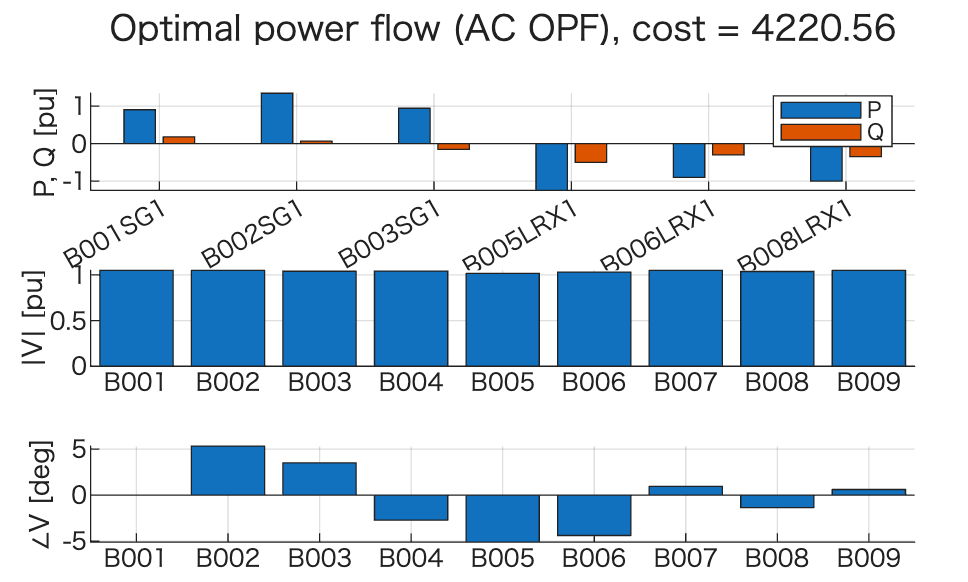

G = resAC.plot_dispatch();

`plot_lmp` は LMP を系統図の母線の色で描きます。効いている制約のあるブランチは選択の色になります。`ColorMode` などの系統図のオプション（Step 7）も使えます。

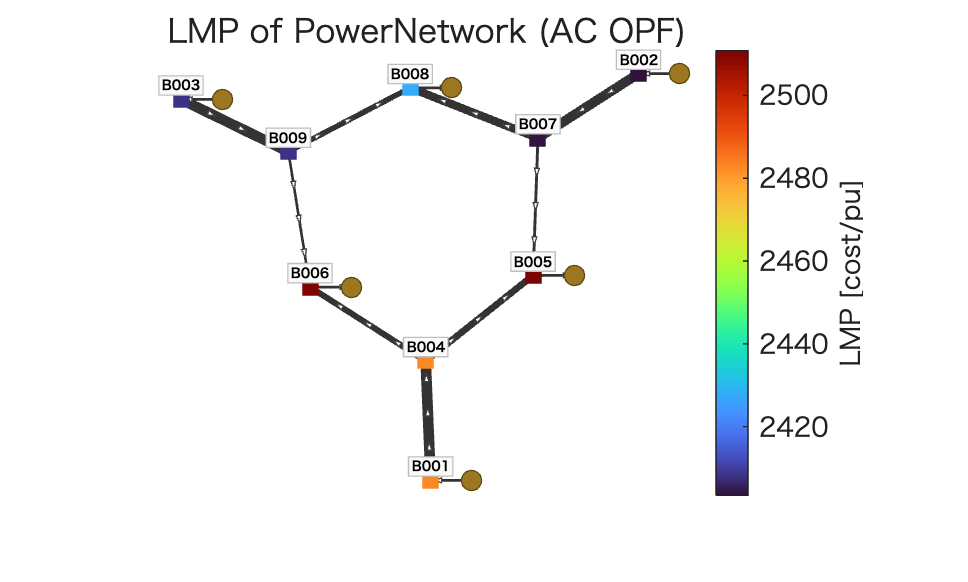

G = resAC.plot_lmp();

`plot_iteration` は AC OPF（fmincon）の反復の様子です。左は費用・制約の違反・発電機の P・母線の |V| の推移、右はその反復での系統図で、スライダーと再生ボタンで反復を選びます。

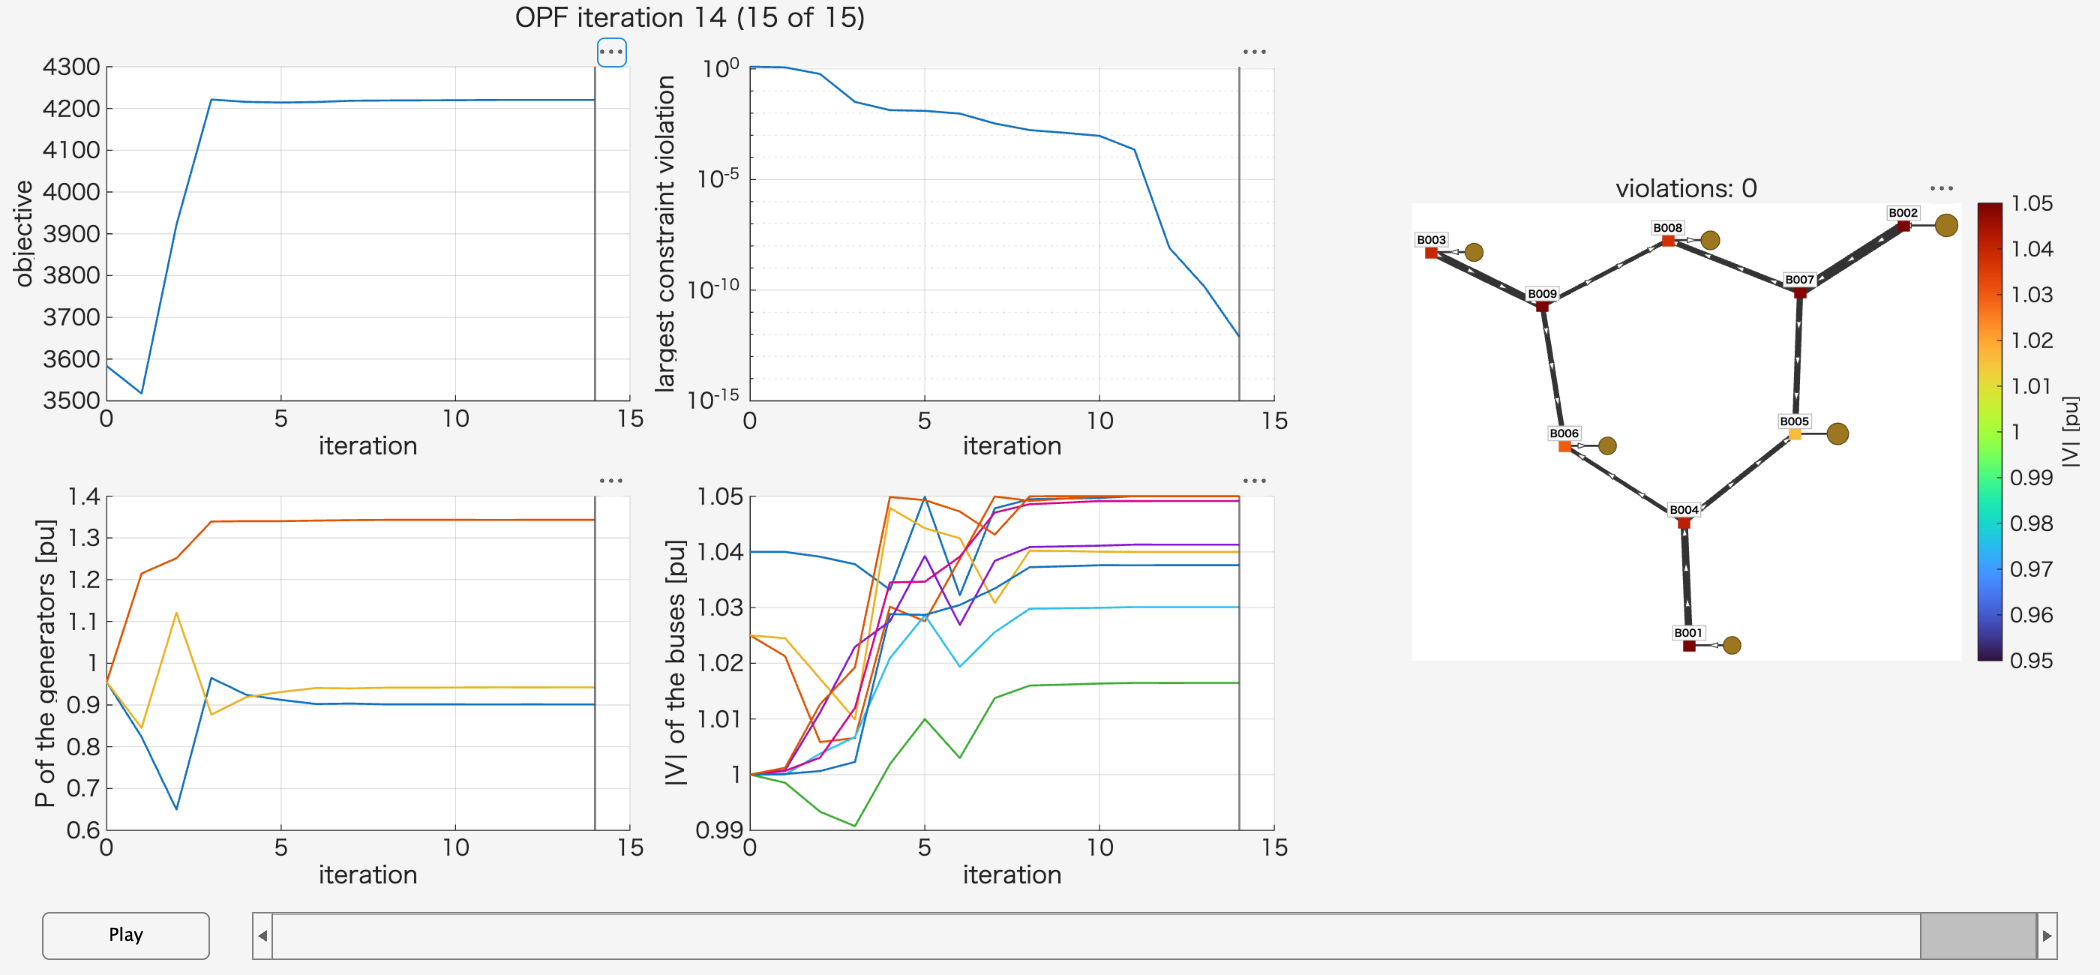

[G_chart, G_net] = resAC.plot_iteration();

**注意:** `plot_iteration` は反復を記録する AC OPF だけで使えます。ELD と DC OPF では `GUILDA:ResultOPF:NoIteration` で止まります。結果は `resAC.export("opf.csv")` でファイルに書き出せます。

## 5. 制約が効いたときの結果

安い G2 から送り出す線路 EL008（母線 B007–B008）の有効電力の上限を 0.4 pu にして、もう一度解きます。

tab_br = net.get_parameter("operation", Class="Branch");
tab_br{"EL008", "Pmax"} = 0.4;
net.set_parameter("operation", tab_br("EL008", "Pmax"));
resCong = net.calculate_optimal_powerflow(Method="AC OPF");

線路の制約が効くと、母線ごとに LMP が分かれます。系統図で見ます。

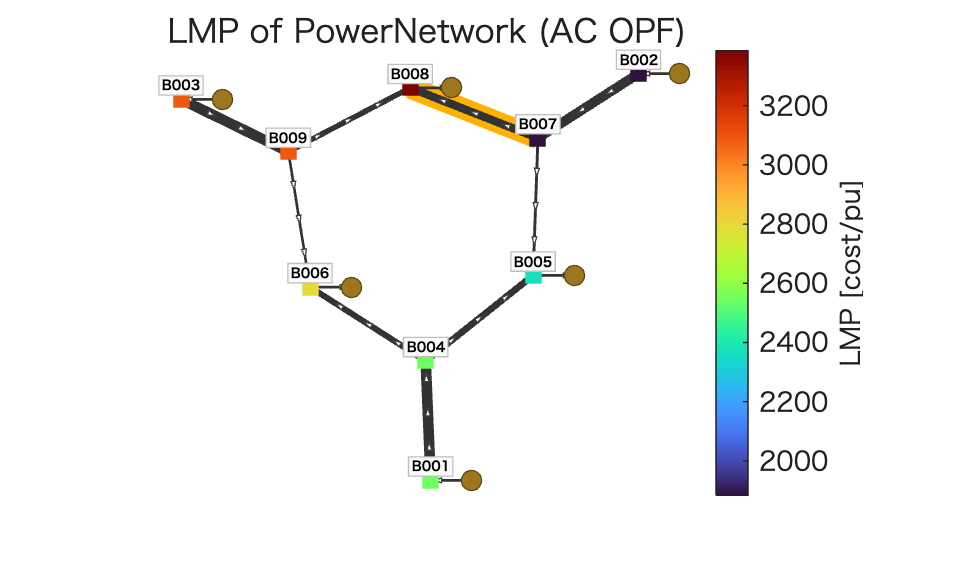

G = resCong.plot_lmp();

後の節のために、上限を元に戻します。

tab_br{"EL008", "Pmax"} = Inf;
net.set_parameter("operation", tab_br("EL008", "Pmax"));

**確かめる（省略できます）**

効いているブランチの制約と、母線ごとの LMP を表示します（制約がないときは 2400〜2500 程度でした）。

resCong.disp_binding(Kind="Branch");

Binding constraints (1) of the OPF result of PowerNetwork
         Constraint            Object       Value    Limit    Multiplier
    ____________________    ____________    _____    _____    __________

    "Pmax_EL008_B007(2)"    "EL008_B007"     0.4      0.4       1652.4  



resCong.get_lmp()

ans = 9×4 table
             LMP      Energy    Congestion     Loss  
            ______    ______    __________    _______

    B001    2545.7    2545.7           0            0
    B002    1883.3    2545.7     -599.16       -63.18
    B003    3092.2    2545.7      627.74      -81.173
    B004    2545.7    2545.7      6.1712      -6.1712
    B005    2368.4    2545.7     -195.06       17.824
    B006    2796.9    2545.7      234.81       16.394
    B007    1884.1    2545.7     -591.47      -70.073
    B008      3386    2545.7      898.25      -57.897
    B009    3092.2    2545.7      633.98      -87.411


## 6. 自分の費用と制約を加える: Cost・Constraint

`Cost` と `Constraint` に関数 `@(v, p)` を渡すと、その呼び出しだけ費用と制約を加えます。`v` は変数で、`v.Component.(タグ).P`、`v.Bus.(タグ).V`、`v.Branch.(タグ).Pfrom` のようにタグで引きます。`p` には `p.Method` と `p.base` があります。

G1 と G2 の出力の余裕（上限 2 pu までの残り。予備力）の合計を 2 pu 以上にする制約を付けます（G1 と G2 の出力の合計が 2 pu 以下になります）。制約の名前（`Reserve`）は、その乗数の名前にもなります。

fcn_reserve = @(v, p) struct("Reserve", ...
    (2 - v.Component.B001SG1.P) + (2 - v.Component.B002SG1.P) >= 2);
resRes = net.calculate_optimal_powerflow(Method="DC OPF", Constraint=fcn_reserve);

費用を加えるときは、スカラーを返す関数を渡します。G3 の出力に 1 pu あたり 200 の費用を足してみます。

resCost = net.calculate_optimal_powerflow(Method="DC OPF", Cost=@(v, p) 200 * v.Component.B003SG1.P);

**確かめる（省略できます）**

予備力の制約を付けた解の出力と、その乗数です。制約がない DC OPF（G1 と G2 の合計は約 2.2 pu）に比べて、高い G3 の出力が増えます。乗数は、予備力を 1 pu 増やしたときの費用の増え方です。

resRes.tab_cub(["B001SG1", "B002SG1", "B003SG1"], "P")

ans = 3×1 table
                  P   
               _______

    B001SG1    0.77436
    B002SG1     1.2256
    B003SG1       1.15


resRes.lambda.Constraints.Reserve

ans = 713.9103

G3 に費用を足した解の出力です。

resCost.tab_cub(["B001SG1", "B002SG1", "B003SG1"], "P")

ans = 3×1 table
                  P   
               _______

    B001SG1    0.89122
    B002SG1     1.3769
    B003SG1    0.88191


### 問題を直接書き換える: build_opf_problem・Problem

`build_opf_problem` は、OPF の最適化問題（`optimproblem`）と初期点を返します。問題を書き換えて `Problem` に渡すと、その問題を解きます。G2 の出力を 1.2 pu 以下にする制約を加えます。

[prob, x0] = net.build_opf_problem(Method="DC OPF");
prob.Constraints.CapG2 = prob.Variables.B002SG1 <= 1.2;
resProb = net.calculate_optimal_powerflow(Method="DC OPF", Problem=prob, InitialPoint=x0);

**確かめる（省略できます）**

resProb.tab_cub(["B001SG1", "B002SG1", "B003SG1"], "P")

ans = 3×1 table
                 P   
               ______

    B001SG1    0.9414
    B002SG1       1.2
    B003SG1    1.0086


**注意:** `Problem` を渡したときは、`Cost`、`Constraint`、`DefaultCost`、`ReferenceBus` は使いません。変数を加えたときは `InitialPoint` にその初期値も入れます。

## 7. 安定度制約付き OPF

AC OPF に、解の運転点での振動モードのダンピング比の下限（`MinDampingRatio`）や、固有値の実部の上限（`MaxRealPart`）を加えます。外側の反復で「OPF → 線形化 → 固有値」を繰り返し、制約を線形化して加えます。動特性のモデルを使うので、系統は `initialize` 済みである必要があります。

制約を付けない AC OPF の解では、最小のダンピング比は約 4.13% です（下の「確かめる」で確かめられます）。これを 4.2% 以上にする条件を付けて解きます（10 秒ほどかかります）。

[resStab, flagStab] = net.calculate_optimal_powerflow(Method="AC OPF", MinDampingRatio=0.042);

費用は制約なしより少し高くなり、その代わりに最小のダンピング比が下限を満たします。外側の反復が上限に達しても条件を満たさないときは flag が 0 になります。

**確かめる（省略できます）**

制約を付けない AC OPF の解での最小のダンピング比を確かめます（`MinDampingRatio=0` は最初の解で満たされるので、1 回解いて固有値を調べるだけです）。

resFree = net.calculate_optimal_powerflow(Method="AC OPF", MinDampingRatio=0);
resFree.sct_stability.tab_iteration

ans = 1×7 table
    Iteration     Cost     MinDampingRatio    MaxRealPart    CriticalMode       Step        Flag
    _________    ______    _______________    ___________    ____________    ___________    ____

        1        4220.6       0.041292        -0.0072129          ""         0.1    0.02     1  


制約を付けた解の flag と反復の記録です。`sct_stability.tab_iteration` の 1 行が外側の反復 1 回で、費用、最小のダンピング比、実部の最大、制約を作ったモード（`CriticalMode`）、設定値を動かせる幅（`Step`）です。

flagStab

flagStab =     OptimalSolution


resStab.sct_stability.tab_iteration

ans = 5×7 table
    Iteration     Cost     MinDampingRatio    MaxRealPart               CriticalMode                    Step        Flag
    _________    ______    _______________    ___________    ___________________________________    ____________    ____

        1        4220.6       0.041292        -0.0072129     "B003SG1 1.35 Hz, B002SG1 0.698 Hz"     0.1    0.02     1  
        2        4243.7       0.041683        -0.0072464     "B003SG1 1.37 Hz, B002SG1 0.695 Hz"     0.1    0.02     1  
        3        4222.5       0.040943        -0.0071934     "B003SG1 1.33 Hz, B002SG1 0.683 Hz"    0.05    0.01     1  
        4        4227.5       0.041867        -0.0072399     "B003SG1 1.36 Hz, B002SG1 0.69 Hz"     0.05    0.01     1  
        5        4245.3       0.042344        -0.0072576     "B003SG1 1.36 Hz, B002SG1 0.684 Hz"    0.05    0.01     1  


`tab_mode` は最後の解のモードの表で、`Owner` はそのモードにいちばん大きく参加している機器や制御器です（Step 8 の `get_mode` と同じ形です）。

resStab.sct_stability.tab_mode

ans = 17×4 table
       Eigenvalue        Frequency    DampingRatio       Owner    
    _________________    _________    ____________    ____________

     -100.02+0i                 0            NaN      "B001SG1CP2"
     -100.13+0i                 0            NaN      "B002SG1CP2"
     -100.15+0i                 0            NaN      "B003SG1CP2"
     -66.635+0i                 0            NaN      "B001SG1CP2"
     -66.484+0i                 0            NaN      "B002SG1CP2"
      -66.46+0i                 0            NaN      "B003SG1CP2"
     -19.592+0i                 0            NaN      "B001SG1CA1"
     -19.912+0i                 0            NaN      "B001SG1CA1"
     -19.938+0i                 0            NaN      "B003SG1CA1"
     -0.3623+8.5484i       1.3605       0.042344      "B003SG1"   
    -0.23359+4.2997i      0.68432       0.054247      "B002SG1"   
    -0.50431+0.39891i    0.063488         0.7843      "B001SG1"   
    -0.38969+0i                 0           

**注意:** 安定度制約付き OPF は `"AC OPF"` だけで使えます。下限を高くするほど反復が増え、時間がかかります。反復の上限、設定値を動かせる幅、目標に持たせる余裕などのオプションは、`calculate_optimal_powerflow` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=calculate_optimal_powerflow')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

## 次の Step

- 次は Step 10: 連続潮流計算です。

- 経済負荷配分、混雑と LMP、安定度制約付き OPF の考え方は Part 6: 最適潮流計算で学びます。

[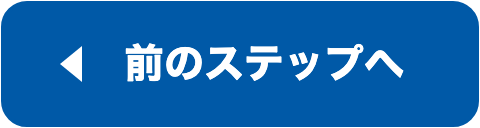](matlab:open('Step8_Linearization.mlx'))　　[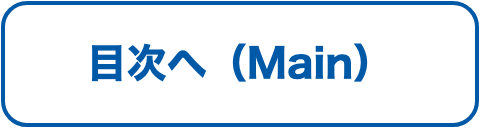](matlab:open('Main.mlx'))　　[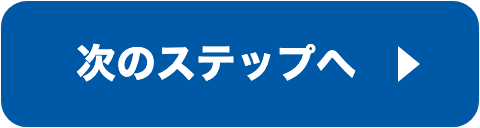](matlab:open('Step10_ContinuationPowerFlow.mlx'))